Task1:

Assumption:

Fire is only a candle

Parrot minidrone moves forward until a fire is detected. If a fire is detected the drone flies as long as the fire is not visible any more. Reason: to get a better image from the situation. 

During this flight persons and cars are detected. 

Drone turns and flies back until a green piece (f.e green a4 paper) is detected.

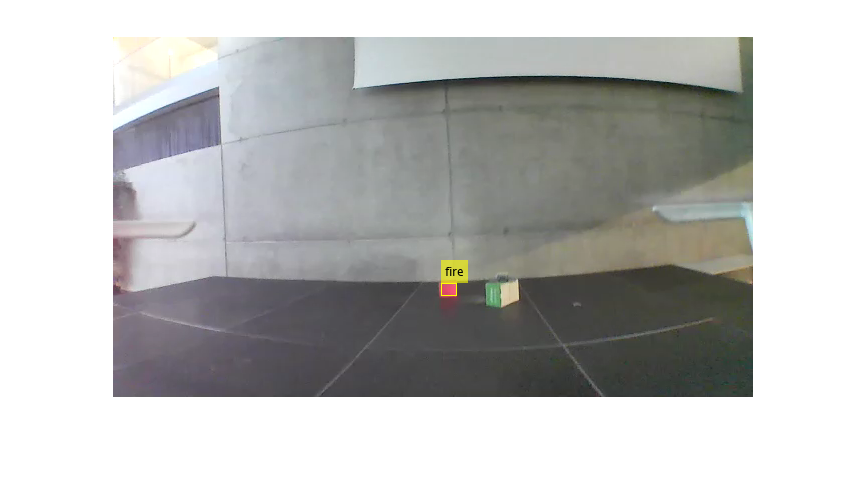

pause('on')
parrotObj = parrot();

takeoff(parrotObj);
movedown(parrotObj,0.01,0.5);
% [height,time] = readHeight(parrotObj)
camObj = camera(parrotObj,'FPV');
%livestream = preview(camObj)

[odSnaps,facesCounter, carsCounter, snap, fireBoundBox, fireFound] = flyForwardUntilFireFound(true, parrotObj, camObj);

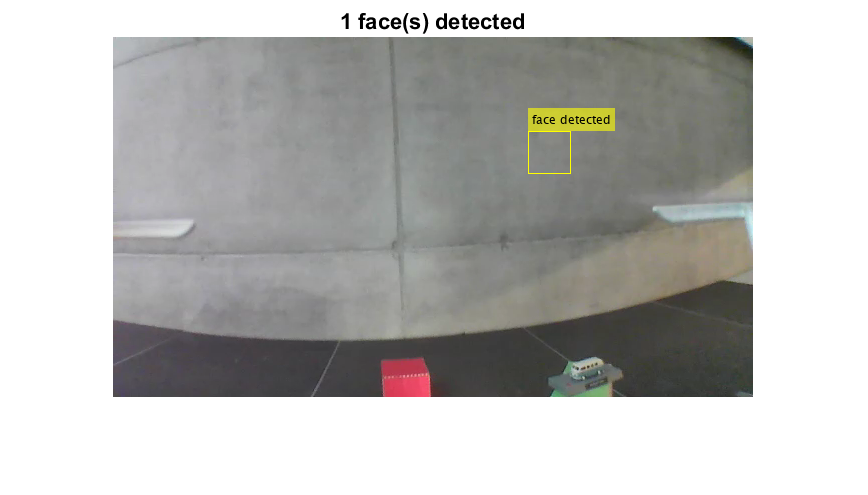

pause(1);
if (fireFound)
    [odSnaps,facesCounter, carsCounter, ~, ~, fireNotFound] =   flyForwardUntilFireFound(false, parrotObj, camObj);
end


pause(1);
turn(parrotObj,deg2rad(-180));
pause(1);

while ~findGreenEndpoint(snapshot(camObj))
    %moveforward(parrotObj,flightDuration);
    move(parrotObj, 0.2,'roll' ,deg2rad(-2), 'pitch', deg2rad(0));
    pause(2);
end

pause('off')
land(parrotObj);

clear parrotObj;
clear camObj;

